# Choosing a Model

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and plots the data.

data = readtable("./data/dataSine.xlsx", Sheet="data");
dataTrain = readtable("./data/dataSine.xlsx", Sheet="dataTrain");
dataTest = readtable("./data/dataSine.xlsx", Sheet="dataTest");
whos data dataTrain dataTest

  Name             Size            Bytes  Class    Attributes

  data           200x2              4387  table              
  dataTest        60x2              2147  table              
  dataTrain      140x2              3427  table              



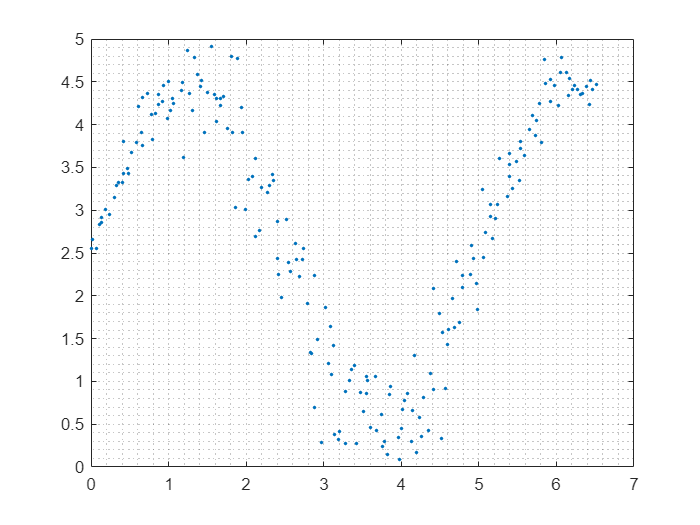

plot(data.x, data.y, ".")
grid minor

## Fit a model

The table `data` has been split into a training set, `dataTrain`, and a test set, `dataTest`. The response variable is `"y"`.

Fit a model 

mdl = fitrsvm(dataTrain, "y", "KernelFunction", "gaussian");

Evaluate at test values.

mdlLoss = loss(mdl, dataTest)

mdlLoss = 0.1251

yPred = predict(mdl, dataTest);

Plot the response.

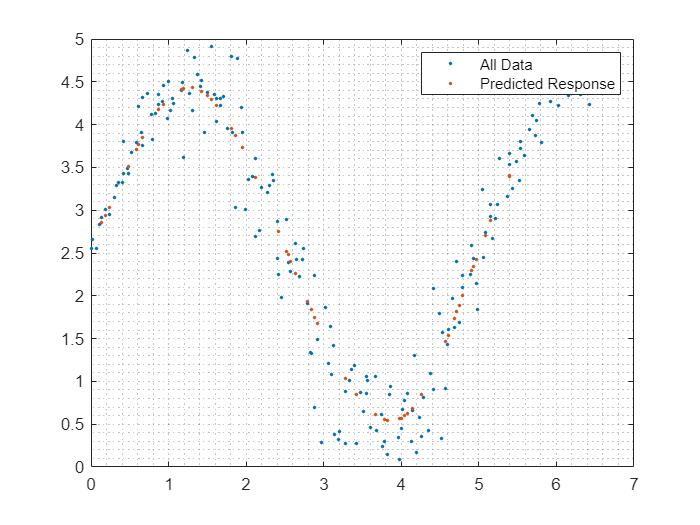

plot(data.x, data.y, ".")
hold on
plot(dataTest.x, yPred, ".")
grid minor
hold off
legend("All Data", "Predicted Response")